%{ 
Group 3:
1. Steve Vinsensius Jo - V01099466
2. Likkhith Krishnamurthy Aditya - V01098937
%}

Task 1:

Use Matlab’s neural network tool box (accessibly via the nnstart command and picking the “Pattern Recognition” option) to create shallow neural network employing one hidden layer and use this network to produce a 3 class decision boundary for the same 3 class data that you originally generated for Exercise 1.

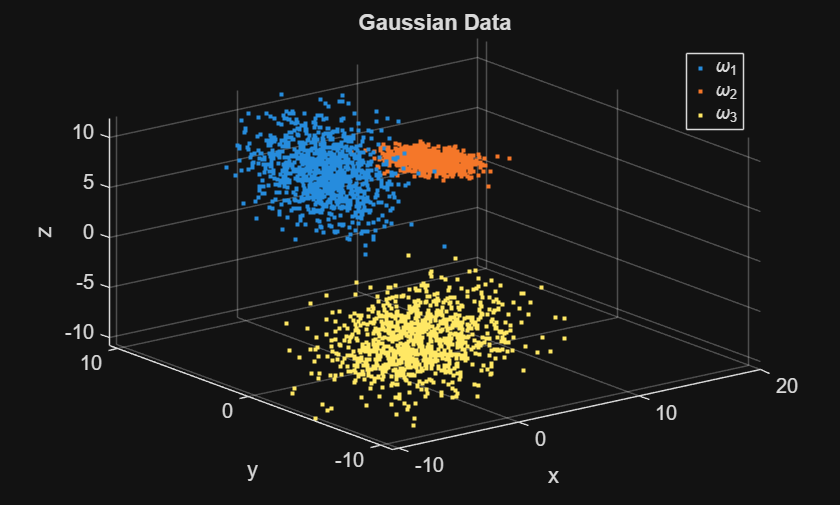

load('exercise1_data.mat');

ex1data(:,:,1) = samples_A';
ex1data(:,:,2) = samples_B';
ex1data(:,:,3) = samples_C';

NDIMS = size(ex1data, 1);
NDATA_per_class = size(ex1data, 2);
NCLASS = size(ex1data, 3);
NDATA = NDATA_per_class * NCLASS;

predictors = reshape(ex1data, NDIMS, []);
responses = full(ind2vec([ones(1,NDATA_per_class), ...
    2*ones(1,NDATA_per_class), 3*ones(1,NDATA_per_class)]));

figure
hold on
for class_i = 1:NCLASS
    scatter3(ex1data(1,:,class_i), ex1data(2,:,class_i), ex1data(3,:,class_i), '.')
end
title('Gaussian Data')
xlabel('x'), ylabel('y'), zlabel('z')
legend({'\omega_1', '\omega_2', '\omega_3'})
view(3)
grid on
hold off


% Train a multiclass neural network classifier
hiddenLayerSize = 10;
% use 'fitcnet' if 'patternnet' no longer compatible in newer version
net = patternnet(hiddenLayerSize, 'trainscg');

rng(573);
datainds = randperm(NDATA);
NTRAIN = round(0.6 * NDATA);
NVAL   = round(0.1 * NDATA);
NTEST  = NDATA - NTRAIN - NVAL;

traininds = datainds(1:NTRAIN);
valinds   = datainds(NTRAIN+1:NTRAIN+NVAL);
testinds  = datainds(NTRAIN+NVAL+1:end);

net.divideFcn = 'divideind';
net.divideParam.trainInd = traininds;
net.divideParam.valInd   = valinds;
net.divideParam.testInd  = testinds;

% Remove default min-max normalization
net.inputs{1}.processFcns = {};

% retrain the network
net = init(net);
net.trainParam.showWindow = false;
[net, trainingRecord] = train(net, predictors, responses);

% Evaluate network performance
y = net(predictors);
tind = vec2ind(responses);
yind = vec2ind(y);

% Error on test set only (not full dataset)
% ~= not equal sign
percentError_test = sum(tind(testinds) ~= yind(testinds)) / numel(testinds) * 100;
fprintf('Test error: %.2f%%\n', percentError_test);

Test error: 0.67%



% Overall error (for reference)
percentError_all = sum(tind ~= yind) / numel(tind) * 100;
fprintf('Overall error: %.2f%%\n', percentError_all);

Overall error: 0.50%



% What was built and how training ended
fprintf('Network: %d inputs -> %d %s hidden neurons -> %d %s outputs, %d weights and biases\n', ...
    net.inputs{1}.size, net.layers{1}.size, net.layers{1}.transferFcn, ...
    net.layers{2}.size, net.layers{2}.transferFcn, net.numWeightElements);

Network: 3 inputs -> 10 tansig hidden neurons -> 3 softmax outputs, 73 weights and biases


fprintf('Data split: %d training, %d validation, %d test samples\n', ...
    numel(traininds), numel(valinds), numel(testinds));

Data split: 1800 training, 300 validation, 900 test samples


fprintf('Training ran %d epochs and stopped with "%s"; the weights from epoch %d were kept\n', ...
    trainingRecord.num_epochs, trainingRecord.stop, trainingRecord.best_epoch);

Training ran 19 epochs and stopped with "Training finished: Met validation criterion"; the weights from epoch 13 were kept


This is the network that Pattern Recognition app creates: three inputs, one hidden layer of 10 neurons using tanh activation function (tansig), three softmax neurons as outputs, 73 weights and biases overall, trained by scaled conjugate gradient method to minimize cross-entropy. After each training epoch the cross-entropy of the validation samples is calculated. Training stops when there were six consecutive epochs without improvement, and the best validation weights are saved.

Two parameter values are different from the corresponding app default values. First, the train/test/validation division ratio is 60/10/30 instead of 70/15/15 used by the app; also, it is done by division indices instead of random division. This results in 900 test samples instead of 450 test samples used by the app. Second, the default min-max input normalization (mapminmax) is switched off.

Task 2

Plot the 3 class decision boundaries created by this trained neural network classifier and discuss the ”correctness” of these boundaries versus the Bayesian class boundaries that were generated in Exercise 2. Why do the the neural network and Bayes methods produce different and distinct boundaries? Which boundary is “better” and why?

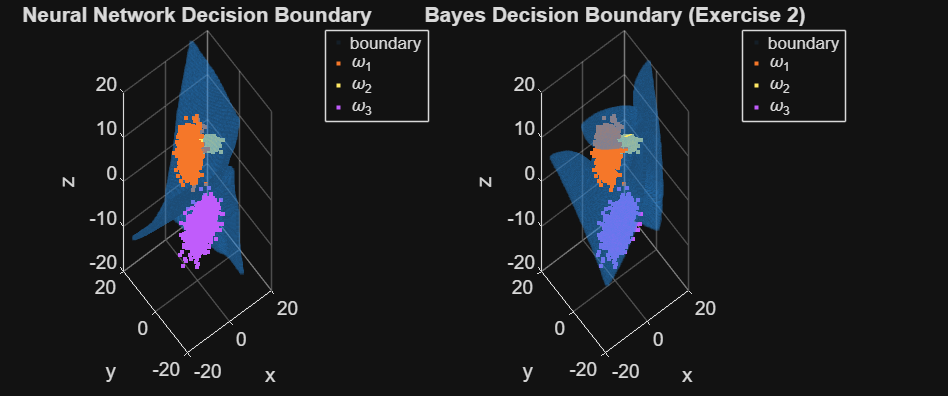

% Same volume and grid as in Exercise 2, so the boundaries can be compared directly
Vaxis = [-15 20 -15 20 -15 20];
Num = 120;
probevol = vol3D(Vaxis, Num)';

% Neural network boundary: grid points where the class changes between neighbors
y_grid = net(probevol);
class_grid = vec2ind(y_grid);
bound_mask = boundaryMask(class_grid, Num);

% Bayes boundary from Exercise 2 (equal priors) on the same grid, same rule
mu_A = [0; 4; 7];
sigma_A = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
mu_B = [10; 5; 5];
sigma_B = [3.0184, 0.4331, -1.4481; 0.4331, 0.9436, -0.6456; -1.4481, -0.6456, 1.2880];
mu_C = [-2; -5; -5];
sigma_C = [6.8928, -1.3750, 3.1945; -1.3750, 3.3572, 0.6945; 3.1945, 0.6945, 3.7500];

bayes_grid = bayesClass(probevol', mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C);
bayes_mask = boundaryMask(bayes_grid, Num);

figure('Position', [100 100 1200 500])
subplot(1, 2, 1)
plotBoundaryCloud(probevol, bound_mask, ex1data, 'Neural Network Decision Boundary')
subplot(1, 2, 2)
plotBoundaryCloud(probevol, bayes_mask, ex1data, 'Bayes Decision Boundary (Exercise 2)')

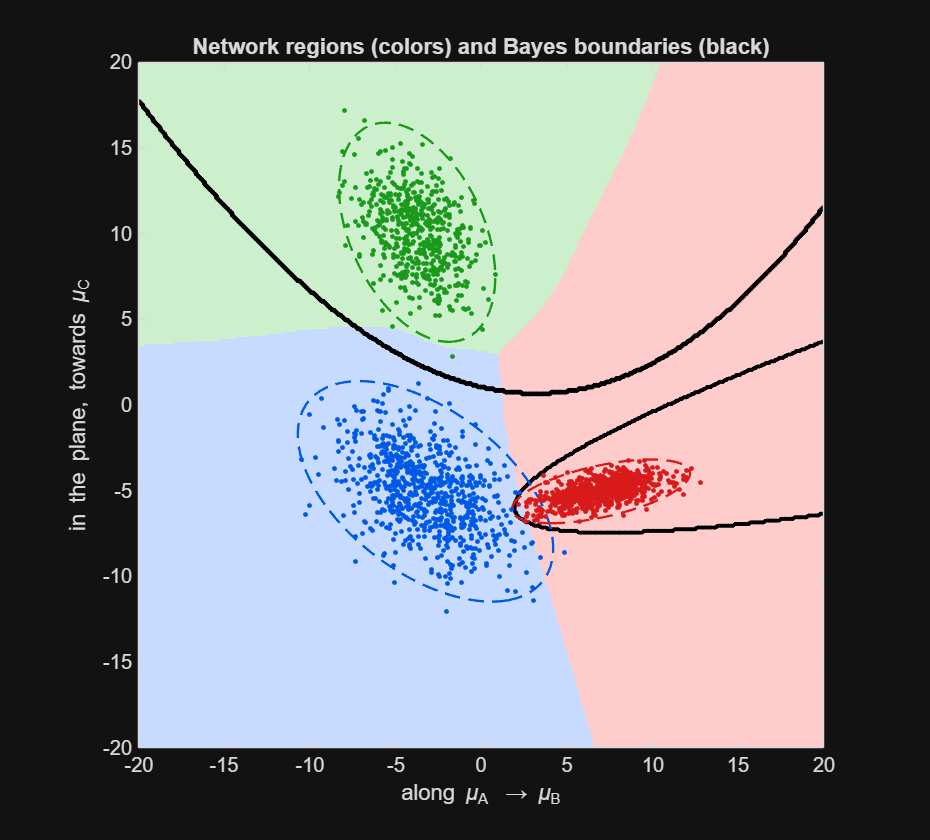


Xrows  = predictors';
labels = vec2ind(responses)';
regionColor = [0.78 0.86 1.00; 1.00 0.80 0.80; 0.80 0.94 0.80];
classColor  = [0.00 0.35 0.90; 0.85 0.10 0.10; 0.10 0.60 0.10];

[P, sAx, rAx, o, e1, e2] = meanPlane(mu_A, mu_B, mu_C, 20, 401);
nnPlane    = vec2ind(net(P'))';
bayesPlane = bayesClass(P, mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C)';
md2P = [mahal2(P, mu_A, sigma_A), mahal2(P, mu_B, sigma_B), mahal2(P, mu_C, sigma_C)];

figure('Position', [100 100 620 560])
drawSlice(sAx, rAx, nnPlane, bayesPlane, md2P, Xrows, labels, o, e1, e2, regionColor, classColor);
title('Network regions (colors) and Bayes boundaries (black)')



inRegion = min([mahal2(probevol', mu_A, sigma_A), mahal2(probevol', mu_B, sigma_B), mahal2(probevol', mu_C, sigma_C)], [], 2)' <= 9;

rng(2026);
N_FRESH = 200000;
freshX = [mvnrnd(mu_A', sigma_A, N_FRESH); mvnrnd(mu_B', sigma_B, N_FRESH); mvnrnd(mu_C', sigma_C, N_FRESH)]';                       % 3 x 600000
freshT = [ones(1,N_FRESH), 2*ones(1,N_FRESH), 3*ones(1,N_FRESH)];
freshBayes = bayesClass(freshX', mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C);
bayesErr = mean(freshBayes ~= freshT);
freshIn = min([mahal2(freshX', mu_A, sigma_A), mahal2(freshX', mu_B, sigma_B), mahal2(freshX', mu_C, sigma_C)], [], 2)' <= 9;

freshNN = vec2ind(net(freshX));
trueErr = mean(freshNN ~= freshT);

fprintf('Data region: %.1f%% of the cube\n', 100*mean(inRegion));

Data region: 3.3% of the cube


fprintf('Grid points where the network and Bayes disagree: %.1f%% of the cube, %.2f%% inside the data region, %.1f%% outside it\n', ...
    100*mean(class_grid ~= bayes_grid), 100*mean(class_grid(inRegion) ~= bayes_grid(inRegion)), ...
    100*mean(class_grid(~inRegion) ~= bayes_grid(~inRegion)));

Grid points where the network and Bayes disagree: 45.1% of the cube, 0.97% inside the data region, 46.6% outside it


fprintf('Fresh samples on which they disagree: %.3f%%\n', 100*mean(freshNN ~= freshBayes));

Fresh samples on which they disagree: 0.475%


fprintf('True error on %d fresh samples: Bayes %.3f%%, network %.3f%%\n', 3*N_FRESH, 100*bayesErr, 100*trueErr);

True error on 600000 fresh samples: Bayes 0.298%, network 0.615%


fprintf('%.1f%% of the fresh samples fall outside the data region. Error rate inside / outside it:\n', 100*mean(~freshIn));

2.8% of the fresh samples fall outside the data region. Error rate inside / outside it:


fprintf('   network %.3f%% / %.2f%%    Bayes %.3f%% / %.2f%%\n', ...
    100*mean(freshNN(freshIn) ~= freshT(freshIn)), 100*mean(freshNN(~freshIn) ~= freshT(~freshIn)), ...
    100*mean(freshBayes(freshIn) ~= freshT(freshIn)), 100*mean(freshBayes(~freshIn) ~= freshT(~freshIn)));

   network 0.415% / 7.68%    Bayes 0.274% / 1.14%


Both sets of boundaries are computed on the same grid as in Exercise 2, using the same rule: a grid point is a boundary point when its class differs from a neighbor's. The second figure shows both classifiers in the plane through the three class means. The colored regions are the network's decisions and the black curves are the Bayes boundaries. In the printout, the data region is the set of grid points within 3 Mahalanobis units of a class mean, and the true error is measured on 600,000 fresh samples drawn from the three Gaussians.

With the data, the boundaries of the network are almost perfect. Within the data area, there is a small disagreement between the network and the Bayes classifier in terms of their respective grids and new data points (listed above). With data away from the regions where it exists, there is nothing common between the two. In the mean plane, Bayes allocates class B only a tiny area, whereas the network allocates class B whatever area its hidden units produce.

The boundaries differ because the neural network boundary is data driven: it separates the classes by minimizing the cross-entropy loss on the training data, and it never estimates the class distributions. Where there are no training samples, nothing constrains it. Far from the data its tanh units saturate and its boundaries flatten into nearly flat sheets, while the Bayes boundaries, computed from the true Gaussian distributions, keep curving. A finite number of tanh units can also only approximate the quadratic Bayes boundaries. Finally, the network's boundary depends on its random training sample and random initial weights.

The Bayes boundary is better, since it directly minimizes the misclassification probability based on the true distributions. Its error (about 0.31%) is the lowest any classifier can reach, and the network's true error is higher (printed above). Most of the visible disagreement lies where there is almost no data, so it hardly changes the error. However, the Bayes boundary is only better because the Gaussian model is exactly right here. In a real problem the true densities are unknown, and a Bayes classifier built on the wrong model can do worse than a network.

Task 3

Discuss whether or not (and why) Matlab’s computation of the trained neural network’s error is correct as in its default implementation within Matlab’s neural net toolbox.

To assess this you will need to look in detail as what is being done by and within the script created by Matlab’s nprtool. Does the produced script compute errors in the way that you expect it should? (or in a way that would be useful to assess the real-world performance of a trained system?) How would you expect that the error for a trained neural network should be reported?

x = predictors;
t = responses;
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0051

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.0050


trainTargets = t .* trainingRecord.trainMask{1};
valTargets   = t .* trainingRecord.valMask{1};
testTargets  = t .* trainingRecord.testMask{1};
trainPerformance = perform(net,trainTargets,y)

trainPerformance = 0.0043

valPerformance   = perform(net,valTargets,y)

valPerformance = 0.0049

testPerformance  = perform(net,testTargets,y)

testPerformance = 0.0068


y_all = net(predictors);
tind  = vec2ind(responses);
yind  = vec2ind(y_all);

percentError_all   = sum(tind ~= yind) / numel(tind) * 100;
percentError_train = sum(tind(traininds) ~= yind(traininds)) / numel(traininds) * 100;
percentError_val   = sum(tind(valinds)   ~= yind(valinds))   / numel(valinds)   * 100;
percentError_test  = sum(tind(testinds)  ~= yind(testinds))  / numel(testinds)  * 100;

fprintf('Full dataset error (default): %.2f%%\n', percentError_all);

Full dataset error (default): 0.50%


fprintf('Training error:               %.2f%%\n', percentError_train);

Training error:               0.33%


fprintf('Validation error:             %.2f%%\n', percentError_val);

Validation error:             1.00%


fprintf('Test error (correct):         %.2f%%\n', percentError_test);

Test error (correct):         0.67%



nTestErr = sum(tind(testinds) ~= yind(testinds));
[~, ciTest] = binofit(nTestErr, numel(testinds));
fprintf('Test errors: %d of %d samples, 95%% confidence interval %.2f%% to %.2f%%\n', ...
    nTestErr, numel(testinds), 100*ciTest(1), 100*ciTest(2));

Test errors: 6 of 900 samples, 95% confidence interval 0.25% to 1.45%


fprintf('True error (%d fresh samples): %.3f%%    Bayes error: %.3f%%\n', 3*N_FRESH, 100*trueErr, 100*bayesErr);

True error (600000 fresh samples): 0.615%    Bayes error: 0.298%


The error calculation in the script produced by nprtool is based on performance and percentErrors of y=net(x), which means the entire data set. This is the same data that was used for training the neural network and stopping conditions. Hence, the error is biased low and cannot represent the true performance of the neural network. It does not show any sign of overfitting, which is the reason our error on the whole data set is lower than the test error. Moreover, percentErrors is a fraction, and not a percentage, and the perform function calculates cross-entropy, not classification error. The per-subset values calculated by the advanced script using masks in the training record are also cross-entropies.

So the arithmetic is correct, but the number is not useful for judging real-world performance. The error should be calculated only on held-out test data that the training never saw. The validation error is not suitable either, since it was used to choose when to stop. Even the test error is only an estimate: with 900 test samples and a handful of errors, its 95% confidence interval (printed above) is wide.

Thus, the error of the trained neural network has to be calculated on the test samples and the confidence interval has to be provided. It is necessary to repeat the training procedure multiple times or use the k-fold cross-validation and then provide the average value and its spread. It is also recommended to verify the result on another data set and compare it to some simple classifier like nearest neighbors.

Task 4

Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries. Which neural network produced boundary is the “best” boundary? How are you defining ”best”? Which neural network boundary provides the best performance for off-training error or, equivalently, provides the best generalization? What issues arise in comparing the neural network boundaries relative to their classification abilities and their abilities to properly generalize?

    • From the perspective of the Question 4 issues, discuss what would occur relative to the produced decision boundaries if 100 different neural network trainings were conducted.

    • Discuss which of the resulting neural network decision boundaries is the correct boundary (or more or most correct boundary) and how would you formally (or quantitatively) assess which is the “best” boundary? Do each of the produced neural network boundaries have the same decision risk (or error) or do each them have different risks (or errors)? (and discuss why)

    • Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s).

num_runs = 10;
test_errors = zeros(1, num_runs);
test_ci     = zeros(num_runs, 2);
true_errors = zeros(1, num_runs);
dis_region  = zeros(1, num_runs);
dis_cube    = zeros(1, num_runs);
dis_fresh   = zeros(1, num_runs);
nets = cell(1, num_runs);
class_grids  = zeros(num_runs, size(probevol, 2), 'uint8');
plane_labels = zeros(size(P, 1), num_runs);
prob_sum = zeros(3, size(freshX, 2));

for i = 1:num_runs
    rng(i);
    net_i = init(net);
    net_i.trainParam.showWindow = false;
    [net_i, ~] = train(net_i, predictors, responses);

    y_i = net_i(predictors);
    tind = vec2ind(responses);
    yind = vec2ind(y_i);
    nErr = sum(tind(testinds) ~= yind(testinds));
    test_errors(i) = nErr / numel(testinds) * 100;
    [~, ci] = binofit(nErr, numel(testinds));
    test_ci(i,:) = 100*ci;

    y_fresh = net_i(freshX);
    prob_sum = prob_sum + y_fresh;
    true_errors(i) = 100*mean(vec2ind(y_fresh) ~= freshT);
    dis_fresh(i)   = 100*mean(vec2ind(y_fresh) ~= freshBayes);

    class_grids(i,:) = vec2ind(net_i(probevol));
    dis_cube(i)   = 100*mean(class_grids(i,:) ~= bayes_grid);
    dis_region(i) = 100*mean(class_grids(i,inRegion) ~= bayes_grid(inRegion));
    plane_labels(:,i) = vec2ind(net_i(P'))';

    nets{i} = net_i;
    fprintf('Run %d - Test error: %.2f%%, true error: %.3f%%\n', i, test_errors(i), true_errors(i));
end

Run 1 - Test error: 0.78%, true error: 0.665%
Run 2 - Test error: 0.89%, true error: 0.794%
Run 3 - Test error: 0.67%, true error: 0.614%
Run 4 - Test error: 0.78%, true error: 0.615%
Run 5 - Test error: 0.89%, true error: 0.643%
Run 6 - Test error: 0.78%, true error: 0.695%
Run 7 - Test error: 0.67%, true error: 0.621%
Run 8 - Test error: 0.89%, true error: 0.631%
Run 9 - Test error: 0.78%, true error: 0.701%
Run 10 - Test error: 0.56%, true error: 0.569%



Run = (1:num_runs)';
TestErr = test_errors';  TestCI_lo = test_ci(:,1);  TestCI_hi = test_ci(:,2);
TrueErr = true_errors';  DisRegion = dis_region';   DisCube = dis_cube';  DisFresh = dis_fresh';
runTable = table(Run, TestErr, TestCI_lo, TestCI_hi, TrueErr, DisRegion, DisCube, DisFresh)

runTable = 10×8 table
    Run    TestErr    TestCI_lo    TestCI_hi    TrueErr    DisRegion    DisCube    DisFresh
    ___    _______    _________    _________    _______    _________    _______    ________

     1     0.77778     0.31326      1.5959        0.665     1.3433      41.009     0.51167 
     2     0.88889     0.38452      1.7439      0.79367     1.5611       47.43     0.65183 
     3     0.66667     0.24504      1.4454      0.61417      1.183      37.782     0.46667 
     4     0.77778     0.31326      1.5959        0.615      1.122      45.179     0.47933 
     5     0.88889     0.38452      1.7439      0.64333      1.197      38.973     0.51767 
     6     0.77778     0.31326      1.5959      0.69467     1


best_error = min(test_errors);
[best_true, best_true_idx] = min(true_errors);
fprintf('Lowest test error (%.2f%%): run(s) %s\n', best_error, mat2str(find(test_errors == best_error)));

Lowest test error (0.56%): run(s) 10


fprintf('Lowest true error: run %d (true error %.3f%%, test error %.2f%%)\n', ...
    best_true_idx, best_true, test_errors(best_true_idx));

Lowest true error: run 10 (true error 0.569%, test error 0.56%)


fprintf('Test errors range from %d to %d errors out of %d test samples\n', ...
    round(min(test_errors)*numel(testinds)/100), round(max(test_errors)*numel(testinds)/100), numel(testinds));

Test errors range from 5 to 8 errors out of 900 test samples


fprintf('Rank correlation (Spearman) between test error and true error: %.2f\n', ...
    corr(test_errors', true_errors', 'Type', 'Spearman'));

Rank correlation (Spearman) between test error and true error: 0.65



pairs = nchoosek(1:num_runs, 2);
d_cube = zeros(size(pairs, 1), 1);
d_region = d_cube;
for q = 1:size(pairs, 1)
    d = class_grids(pairs(q,1),:) ~= class_grids(pairs(q,2),:);
    d_cube(q)   = 100*mean(d);
    d_region(q) = 100*mean(d(inRegion));
end
fprintf('Pairs of runs disagree on %.1f%% of the cube on average, but on only %.2f%% of the data region\n', ...
    mean(d_cube), mean(d_region));

Pairs of runs disagree on 12.1% of the cube on average, but on only 0.40% of the data region



[~, ens] = max(prob_sum, [], 1);
fprintf('Ensemble (average output of the %d networks): true error %.3f%%\n', num_runs, 100*mean(ens ~= freshT));

Ensemble (average output of the 10 networks): true error 0.618%


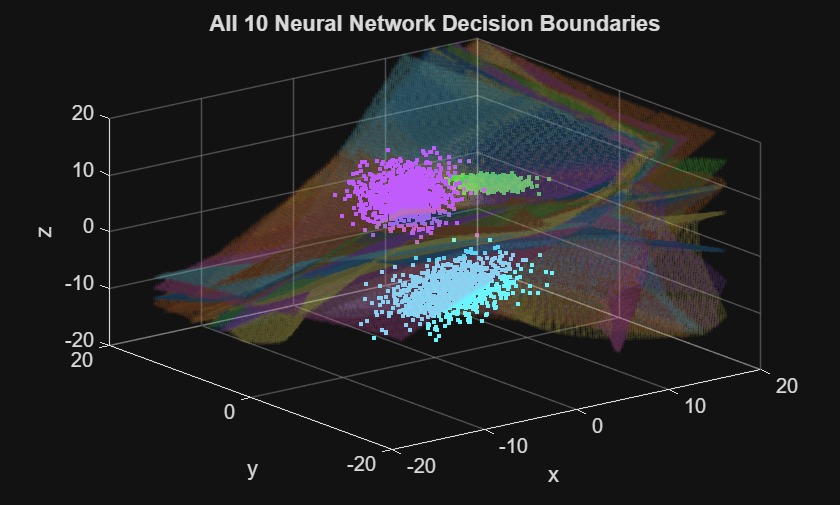


figure
hold on
for i = 1:num_runs
    bound_inds_i = find(boundaryMask(class_grids(i,:), Num));
    scatter3(probevol(1,bound_inds_i), probevol(2,bound_inds_i), probevol(3,bound_inds_i), ...
        '.', 'MarkerEdgeAlpha', 0.05);
end
for class_i = 1:NCLASS
    scatter3(ex1data(1,:,class_i), ex1data(2,:,class_i), ex1data(3,:,class_i), '.')
end
hold off
view(3), grid on
xlabel('x'), ylabel('y'), zlabel('z')
title('All 10 Neural Network Decision Boundaries')

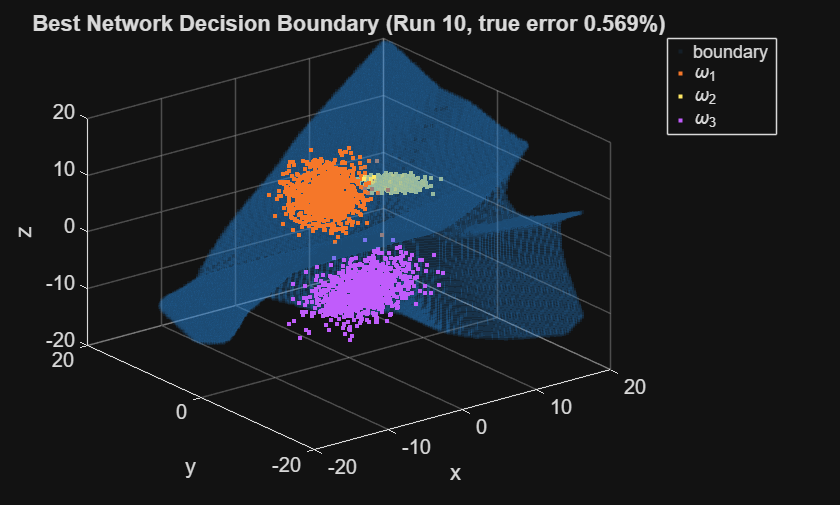


figure
plotBoundaryCloud(probevol, boundaryMask(class_grids(best_true_idx,:), Num), ex1data, ...
    sprintf('Best Network Decision Boundary (Run %d, true error %.3f%%)', best_true_idx, best_true))

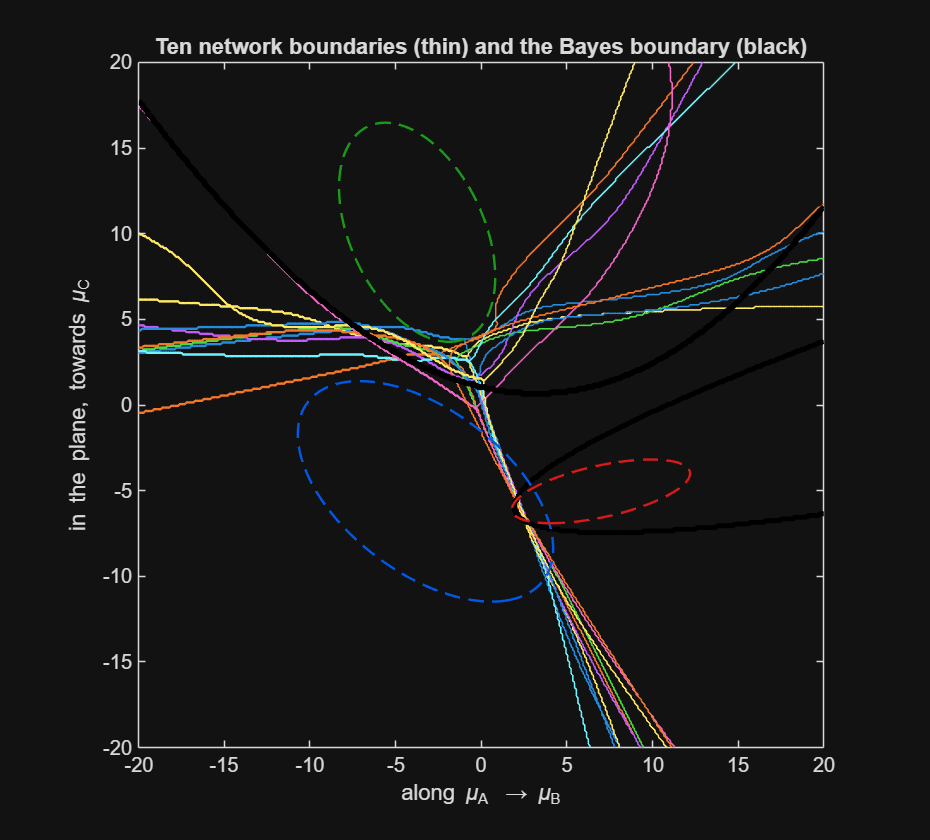


figure('Position', [100 100 620 560])
hold on
nP = numel(sAx);
runColor = lines(num_runs);
for i = 1:num_runs
    contour(sAx, rAx, reshape(plane_labels(:,i), nP, nP), [1.5 2.5], ...
        'LineColor', runColor(i,:), 'LineWidth', 0.8);
end
contour(sAx, rAx, reshape(bayesPlane, nP, nP), [1.5 2.5], 'LineColor', 'k', 'LineWidth', 2.5);
for c = 1:3
    contour(sAx, rAx, reshape(md2P(:,c), nP, nP), [9 9], '--', 'LineColor', classColor(c,:), 'LineWidth', 1.2);
end
hold off
axis equal; axis([sAx(1) sAx(end) rAx(1) rAx(end)]); box on
xlabel('along \mu_A \rightarrow \mu_B'); ylabel('in the plane, towards \mu_C');
title('Ten network boundaries (thin) and the Bayes boundary (black)')

Across 10 runs with different initial weights, the test errors vary by a few tenths of a percent, so even with identical training data the decision boundary depends on the starting weights. Inside the data region the ten boundaries nearly coincide and stay close to the Bayes boundary. Outside it they fan out in different directions, because no sample constrains them there. So two networks with the same test error can still have quite different boundaries in the low-density regions.

We define the best boundary as the one with the lowest true (off-training) error: the probability of misclassifying a new sample, which is exactly what best generalization means. We can measure it here only because we know the distributions (the TrueErr column, from 600,000 fresh samples). The run with the lowest true error is printed above and plotted separately, and it is not necessarily the run with the lowest test error.

Comparing the runs by test error has two problems. First, the differences are not significant: all runs use the same 900 test samples but differ by only a few errors, and their confidence intervals overlap almost completely. Second, picking the lowest test error is biased, because the smallest of ten noisy estimates overstates how good the winner is (the winner's curse). Most of the visible differences between the boundaries are also in empty space, where they barely affect the error.

With 100 trainings, the boundaries inside the data region would form a narrow band around the Bayes boundary, while outside it they would take an ever wider range of shapes. The true errors would form a distribution above the Bayes error, and by chance some runs would get a misleadingly low test error. Rather than picking one network, it is more useful to report the distribution of the error, or to average the networks' outputs into an ensemble (its true error is printed above).

Each network has its own boundary and therefore its own risk, R(h) = ∫ P(error | x, h) p(x) dx, so the runs do not have the same error. Their boundaries differ inside the overlap regions, where p(x) is not negligible, and all of them are above the Bayes risk (about 0.31%). To decide formally which is best, each network should be tested on the same large independent test set, with a confidence interval for each error. Pairs should then be compared with McNemar's test, and one network called better only when the difference is statistically significant.

Each tanh neuron takes one smooth step in one direction, so the more neurons there are, the more bends are possible. With sufficient neurons, they can approximate any smooth boundary (universal approximation theorem), but the problem with one neuron is that it is not enough because it is capable of dividing the input space into parallel slabs. However, the more neurons there are, the more possibilities of overfitting exist, making it even more difficult to predict boundaries outside the training data set. Without early stopping, a large neural network is able to make its training error lower than the Bayes error.

Task 5

Scenario 1: Infinite Neurons and Infinite Data In this scenario, theoretically, Neural network can generate boundary equivalent  to Bayes boundary. Based on Universal Approximation Theorem,  which states that any continuous function can be approximated with arbitrary  precision by a shallow feed-forward  network with a sufficiently large number of  hidden units. If there is infinite training data  that represents the true distribution, then convergence to Bayes' boundary will be achieved.

Scenario 2: Finite Neurons and Finite Data In this scenario, The network is only capable of approximating the Bayes boundary when the true  Bayes boundary is in the function class that the network can approximate. With just 10 hidden units,  the network is limited in terms of what it can do, and it might not be able to approximate the whole  Bayes boundary especially where the classes overlap non-linearly.

Scenario 3: Finite Data regardless of architecture Even with enough neurons, the network will never be able to reconstruct the precise Bayes' boundary  using only finite samples. The parameters learned by the network are merely estimates based on the  sample distribution and not based on the real distribution. As the Bayes' boundary is dependent on knowing the exact means and covariances, it is impossible for the network to ever reach it.

In practice, the decision boundary of the neural network is always just an approximation to the Bayes decision boundary. In summary, the better the approximation gets, the greater the number of neurons used and the greater the amount of training data.

Task 6

Discuss whether or not the neural network boundaries are likely to be more or less sensitive to outliers than the Bayesian boundaries. Provide a discussion of which outliers a neural network approach would be likely to be sensitive to and which types of outliers it may be relatively insensitive to.

Neither method is more robust across the board; they are sensitive to different outliers. The Bayes classifier of Exercise 2 is built from each class's sample mean and covariance, and every point affects these estimates more the farther it is from the class mean, whether or not it is anywhere near a boundary. That is why, in Exercise 2, a single far outlier was enough to move the Bayes boundaries. Label errors close to a boundary matter less for Bayes, because those points lie within a few standard deviations of the means.

The network minimizes the cross-entropy, where each training point's pull on the weights is proportional to y − t, its output minus its target. A point that is already classified correctly with high confidence has y ≈ t and contributes almost nothing, however far away it is. So the network is relatively insensitive to correctly labeled outliers on their own class's side of the boundaries, even very far away. It is sensitive to outliers near or across a boundary, such as mislabeled points and points from the overlap regions, because those are the points that set the boundary. It is also sensitive to groups of mislabeled points, which it can carve out a region for.

One exception is the input scaling. The app's default mapminmax scaling is set by the most extreme value of each input, so a single far outlier would squeeze the real data into a small part of [−1, 1] and change the network. Our network was trained without mapminmax, so it avoids this particular effect.

Task 7:

Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.

If you require that your developed system continues to function correctly for unlabeled real-world data which is many orders of magnitude more voluminous than your training data, then which training regimes would give you more confidence in you end system and why?

For a fixed number of labeled points, every point used in the test set becomes a point which the network does not have the chance to learn from. For 90:10, the network has learned from more points and hence performs better and varies less with respect to runs; however, there are 300 points remaining for testing. With 0.5% error rate, this results in a few mistakes so that the test error is highly noisy: we will have a good network but fail to prove that it is good. For 10:90, on the other hand, the estimation of error is accurate (2700 points remain for testing), but the network learns only 300 points, and thus has relatively larger error and higher variability: we have got a poor network with exact measurement of its error. Our 60/10/30 split is somewhere in the middle.

When there are few training samples, then overfitting becomes easier. In a network that has sufficient capacity, the training error can be made to become zero, lower than Bayes error. This shows that the model has fitted the noise instead of the class structure. When there are many training samples, then there will be little left for the model to overfit. Early stopping works, but it requires a validation set which reduces the number of training samples.

For a system that has to process much more unlabeled data than what it has been trained on, two factors make one confident. First, the error estimate must be precise, and that comes only from a large test set. With n test samples and no errors, the 95% upper bound on the error rate is about 3/n, so our 900 test samples can support a claim of about 0.33% at best, and a claim of 0.01% would need 30,000. Second, the training data must cover the inputs the system will meet. About 2.7% of our samples fall outside the data region, where the network's error rate is highest (Task 2), and at deployment scale that is many thousands of inputs.

The approach that gives the most confidence combines four things: k-fold cross-validation (or repeated random splits) to report the mean and spread of the error, a final network trained on all the data, a large separately collected test set sized with the 3/n rule, and monitoring in operation that flags unfamiliar or low-confidence inputs.

Task 8

Discuss the relatively value and importance of nearest neighbor classification in terms of assessing the performance of higher power classifiers such as neural network methods.

refinds = [traininds, valinds];
K_LIST = [1 3 5 15 51];
k_NN = K_LIST(:);
KnnTestErr = zeros(numel(K_LIST), 1);
KnnTrueErr = zeros(numel(K_LIST), 1);
for i = 1:numel(K_LIST)
    KnnTestErr(i) = 100*mean(knnClass(Xrows(refinds,:), labels(refinds), Xrows(testinds,:), K_LIST(i)) ~= labels(testinds));
    KnnTrueErr(i) = 100*mean(knnClass(Xrows(refinds,:), labels(refinds), freshX', K_LIST(i)) ~= freshT');
end
knnTable = table(k_NN, KnnTestErr, KnnTrueErr)

knnTable = 5×3 table
    k_NN    KnnTestErr    KnnTrueErr
    ____    __________    __________

      1      0.55556       0.39517  
      3      0.44444       0.36333  
      5      0.44444       0.35917  
     15      0.33333       0.38683  
     51      0.33333       0.46017  


fprintf('Networks of Task 4: true error mean %.3f%%, best %.3f%%\n', mean(true_errors), min(true_errors));

Networks of Task 4: true error mean 0.655%, best 0.569%


if min(KnnTrueErr) <= mean(true_errors)
    fprintf('-> The best k-NN classifier matches or beats the average network.\n');
else
    fprintf('-> Every k-NN classifier is worse than the average network.\n');
end

-> The best k-NN classifier matches or beats the average network.



idx2 = knnsearch(Xrows, Xrows, 'K', 2);
looWrong = sum(labels(idx2(:,2)) ~= labels);
looErr = looWrong / numel(labels);
[~, looCI] = binofit(looWrong, numel(labels));
nCls = 3;
chUpper = bayesErr * (2 - nCls/(nCls-1)*bayesErr);
chLower = (nCls-1)/nCls * (1 - sqrt(1 - nCls/(nCls-1)*looErr));
fprintf('Leave-one-out 1-NN error: %d of %d = %.3f%% (95%% CI %.3f%% to %.3f%%)\n', ...
    looWrong, numel(labels), 100*looErr, 100*looCI(1), 100*looCI(2));

Leave-one-out 1-NN error: 11 of 3000 = 0.367% (95% CI 0.183% to 0.655%)


fprintf('Cover-Hart, with the true Bayes error: %.3f%% <= 1-NN error (unlimited data) <= %.3f%%\n', ...
    100*bayesErr, 100*chUpper);

Cover-Hart, with the true Bayes error: 0.298% <= 1-NN error (unlimited data) <= 0.594%


fprintf('Cover-Hart turned around, from the leave-one-out 1-NN error: %.3f%% <= Bayes error <= %.3f%%\n', ...
    100*chLower, 100*looErr);

Cover-Hart turned around, from the leave-one-out 1-NN error: 0.184% <= Bayes error <= 0.367%


Nearest-neighbor classification is a benchmark with no assumptions. It has no weights, no training, no random seed and no model of the classes; it simply copies the labels of the nearest training samples. A network that cannot beat k-NN on the same data is not making good use of its extra complexity. In our code, k-NN uses the same 2100 training and validation samples and the same 900 test samples as the networks, and the printout compares the two directly. In a real problem the Bayes error is unknown, so a baseline like this is often the only thing to compare a network against.

k-NN also encloses the error limit for any classifier. Cover and Hart (1967) proved that with an infinite amount of data, the error of the 1-NN classifier P_1 satisfies the following inequality: P* ≤ P_1 ≤ 2P*, where P* is the Bayes error; therefore, P_1/2 ≤ P* ≤ P_1. The value P_1 can be estimated relatively cheaply using the leave-one-out approach. According to our leave-one-out estimate, the 1-NN error is 0.367% (11 out of 3000 samples), which encloses the Bayes error between 0.18% and 0.37%, while the actual Bayes error value is about 0.31%, and it lies within this interval. This demonstrates the gap in performance that any classifier can have.

Disadvantages of k-NN include its use of all training data for each prediction and dependence on scaling of inputs, as well as the lack of "nearness" of neighbors in higher dimensions, which makes the bound too loose. However, in 3D space and with 3000 samples, k-NN serves as an excellent baseline model.

Task 9

Training and testing data sets are traditionally drawn at random from the full set of available data. Do all data samples have equal impact in determining the location of the problem domain’s given decision boundary? Formally discuss why or why not?

Which data points are the most important in determining the location and shape of a given decision boundary? Does random sampling place and emphasis on these “higher value” data points?

Describe approaches you would take to address this problem with a real-world data analysis system that you were building and that needed to work correctly in full-scale operation.

gX = [discriminant(Xrows, mu_A, sigma_A), discriminant(Xrows, mu_B, sigma_B), discriminant(Xrows, mu_C, sigma_C)];
postX = exp(gX - max(gX, [], 2));
postX = postX ./ sum(postX, 2);              % Bayes posterior of each sample
maxPost = max(postX, [], 2);
fprintf('Samples whose largest Bayes posterior is below 0.999 / 0.99 / 0.9: %d / %d / %d of %d\n', ...
    sum(maxPost < 0.999), sum(maxPost < 0.99), sum(maxPost < 0.9), numel(maxPost));

Samples whose largest Bayes posterior is below 0.999 / 0.99 / 0.9: 193 / 80 / 30 of 3000


u = sort(1 - maxPost, 'descend');
fprintf('Share of the total uncertainty sum(1 - max posterior) held by the 1%% / 5%% least certain samples: %.1f%% / %.1f%%\n', ...
    100*sum(u(1:round(0.01*end)))/sum(u), 100*sum(u(1:round(0.05*end)))/sum(u));

Share of the total uncertainty sum(1 - max posterior) held by the 1% / 5% least certain samples: 74.8% / 98.6%


fprintf('Of the samples with largest posterior below 0.99, %d are in our training set and %d in our test set\n', ...
    sum(maxPost(traininds) < 0.99), sum(maxPost(testinds) < 0.99));

Of the samples with largest posterior below 0.99, 39 are in our training set and 33 in our test set


No, they don’t. The border between the two classes is located at their posterior equality; thus, the location of the border is determined by the samples in the intersection area. Formally, if a network is trained using cross-entropy, the contribution of sample n to the gradient will be ∂E_n/∂w = Σ_i (y_n,i − t_n,i) ∂z_n,i/∂w, where z_n,i are the inputs to the softmax. In the case where sample n is in the middle of its own class region, i.e., y_n ≈ t_n, the contribution to the gradient is nearly zero, while the samples close to the border determine the location of the border.

These boundary samples are rare. Using the Bayes posteriors, only 80 of our 3000 samples (2.7%) have a largest posterior below 0.99. Random sampling does not emphasize them: it picks them only in proportion to how common they are, so our training set received only a few dozen and our test set about two dozen (printed above). Most of the effort goes into samples that teach the network nothing new, and the test error is decided by a couple of dozen samples. Interior samples are still needed, though, to anchor which side of each boundary belongs to which class.

For a real system that must work at full scale, we would focus effort on the boundary while keeping coverage of the rest of the space:

• active learning: label next the samples which the current classifier is the least certain about and then re-train;

• stratified sampling/importance sampling: over-sample the boundary area and re-weight the samples such that the estimates of error are unbiased;

• boosting/hard example mining: over-weight the low margin examples;

• careful examination of the labels in the vicinity of the boundary;

• testing sets where there is over-sampling of the overlap areas;

• monitoring in practice: feed low confidence/unfamiliar samples to get labeled and include them in the training set.

function bound_mask = boundaryMask(class_grid, Num)
class_vol = reshape(double(class_grid), Num, Num, Num);
bound_mask = false(Num, Num, Num);
bound_mask(1:end-1,:,:) = bound_mask(1:end-1,:,:) | (diff(class_vol,1,1) ~= 0);
bound_mask(:,1:end-1,:) = bound_mask(:,1:end-1,:) | (diff(class_vol,1,2) ~= 0);
bound_mask(:,:,1:end-1) = bound_mask(:,:,1:end-1) | (diff(class_vol,1,3) ~= 0);
end


function plotBoundaryCloud(probevol, bound_mask, ex1data, ttl)
bound_inds = find(bound_mask);
hold on
scatter3(probevol(1,bound_inds), probevol(2,bound_inds), probevol(3,bound_inds), ...
    '.', 'MarkerEdgeAlpha', 0.1);
for class_i = 1:size(ex1data, 3)
    scatter3(ex1data(1,:,class_i), ex1data(2,:,class_i), ex1data(3,:,class_i), '.')
end
hold off
view(3), grid on
xlabel('x'), ylabel('y'), zlabel('z')
title(ttl)
legend({'boundary', '\omega_1', '\omega_2', '\omega_3'})
end


function g = discriminant(X, mu, sigma, prior)
if nargin < 4, prior = 1; end
Xc = X - mu';
invSigma = inv(sigma);
quadForm = sum((Xc * invSigma) .* Xc, 2);
g = -0.5*quadForm - 0.5*log(det(sigma)) + log(prior);
end


function c = bayesClass(Xrows, mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C)
[~, c] = max([discriminant(Xrows, mu_A, sigma_A), discriminant(Xrows, mu_B, sigma_B), ...
              discriminant(Xrows, mu_C, sigma_C)], [], 2);
c = c';
end


function q = mahal2(Xrows, mu, sigma)
Xc = Xrows - mu(:)';
q = sum((Xc / sigma) .* Xc, 2);
end


function lab = knnClass(Xref, yref, Xq, k)

N = size(Xq, 1);
lab = zeros(N, 1);
step = 100000;
for i0 = 1:step:N
    rows = i0:min(N, i0 + step - 1);
    idx = knnsearch(Xref, Xq(rows,:), 'K', k);
    votes = reshape(yref(idx), size(idx));
    lab(rows) = mode(votes, 2);
end
end


function [P, sAx, rAx, o, e1, e2] = meanPlane(mu_A, mu_B, mu_C, halfWidth, n)
o  = (mu_A + mu_B + mu_C) / 3;
e1 = (mu_B - mu_A) / norm(mu_B - mu_A);
w  = (mu_C - mu_A) - ((mu_C - mu_A)' * e1) * e1;
e2 = w / norm(w);
sAx = linspace(-halfWidth, halfWidth, n);
rAx = linspace(-halfWidth, halfWidth, n);
[S, Rr] = meshgrid(sAx, rAx);
P = o' + S(:) * e1' + Rr(:) * e2';
end


function drawSlice(sAx, rAx, labP, bayesLabP, md2P, X, labels, o, e1, e2, regionColor, classColor)
n = numel(sAx);
image(sAx, rAx, reshape(double(labP), n, n));
colormap(gca, regionColor);
axis xy; axis equal; axis([sAx(1) sAx(end) rAx(1) rAx(end)]);
hold on
contour(sAx, rAx, reshape(double(bayesLabP), n, n), [1.5 2.5], 'LineColor', 'k', 'LineWidth', 2);
for c = 1:3
    contour(sAx, rAx, reshape(md2P(:,c), n, n), [9 9], '--', 'LineColor', classColor(c,:), 'LineWidth', 1.2);
end
if size(X, 2) ~= 3
    X = X';
end
o = o(:)';  e1 = e1(:);  e2 = e2(:);  labels = labels(:);
nrm  = cross(e1, e2);
D    = X - o;
near = abs(D * nrm) < 1.5;
scatter(D(near,:) * e1, D(near,:) * e2, 6, classColor(labels(near),:), 'filled');
hold off
xlabel('along \mu_A \rightarrow \mu_B'); ylabel('in the plane, towards \mu_C');
end